# ***Control Systems ***

# ***Software hw1***

## ***Dr. Behzad Ahi***

## ***MohammadParsa Dini 400101204***

***Problem 7:*** In this part we will plot some of the given signals versus time.

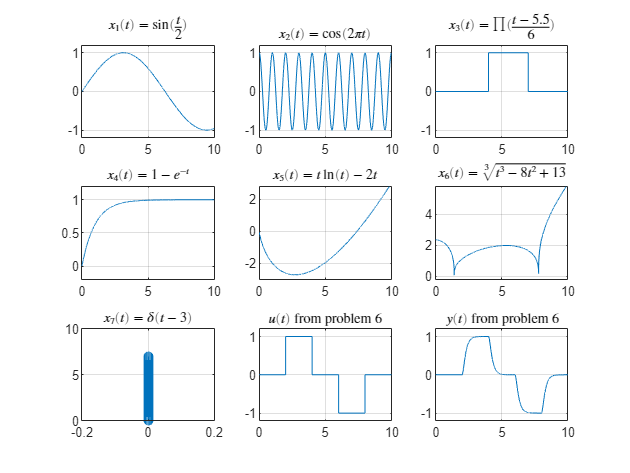

clear all;
close all;
% -------------------------
t_start = 0;
t_end = 10;
% ------ x1
subplot(3,3,1);
Ts1 = 0.001;
t1 = t_start:Ts1:t_end;
x1 = sin(t1/2);
plot(t1,x1);
title("$x_1(t) = \sin(\frac{t}{2})$",Interpreter="latex");
ylim([-1.2,1.2]);
xlim([0,10])
grid on 
% ------ x2
subplot(3,3,2);
Ts2 = 0.001;
t_start = 0;
t_end = 10;
t2 = t_start:Ts2:t_end;
x2 = cos(2*pi*t2);
plot(t2,x2);
title("$x_2(t) = \cos(2\pi t)$",Interpreter="latex");
ylim([-1.2,1.2]);
xlim([0,10])
grid on 
% ------ x3
subplot(3,3,3);
Ts3 = 0.001;
t3 = t_start:Ts3:t_end;
x3 = rectangularPulse(4,7,t3);
plot(t3,x3);
title("$x_3(t) = \prod(\frac{t-5.5}{6})$",Interpreter="latex");
ylim([-1.2,1.2]);
xlim([0,10])
grid on 
% ------ x4
subplot(3,3,4);
Ts4 = 0.001;
t4 = t_start:Ts4:t_end;
x4 = 1 - exp(-t4);
plot(t4,x4);
title("$x_4(t) = 1 - e^{-t}$",Interpreter="latex");
ylim([-.2,1.2]);
xlim([0,10])
grid on 
% ------ x5
subplot(3,3,5);
Ts5 = 0.001;
t5 = t_start+0.01:Ts5:t_end;
x5 = t5.*log(t5) - 2*t5;
plot(t5,x5);
title("$x_5(t) = t\ln(t) - 2t$",Interpreter="latex");
ylim([-3,2.8]);
xlim([0,10])
grid on 
% ------ x6
subplot(3,3,6);
warning('off');
Ts6 = 0.001;
t6 = t_start+0.01:Ts6:t_end;
x6 = (t6.^3 - 8*t6.^2 + 13).^(1/3);
plot(t6,x6);
title("$x_6(t) = \sqrt[3]{t^3 - 8t^2 + 13}$",Interpreter="latex");
ylim([-.2,5.8]);
xlim([0,10])
grid on 
% ------ x7
subplot(3,3,7);
Ts7 = 0.001;
t7 = t_start+0.01:Ts7:t_end;
x7 = dirac(t7-3);
stem(x7,t7-3);
title("$x_7(t) = \delta(t-3)$",Interpreter="latex");
xlim([-.2,.2]);
ylim([0,10])
grid on 
% ------ x8
subplot(3,3,8);
% x(t) and y(t) from problem 6
Ts8 = 0.001;
t8 = t_start:Ts8:t_end;
x8 = (t8 >= 2) & (t8 <= 4);
x8 = x8 - ( (t8 >= 6) & (t8 <= 8));
y8 = (1 - 2*exp(-5*(t8-2))+ exp(-10*(t8-2))).*(t8>=2); 
y8 = y8 - (1 - 2*exp(-5*(t8-4))+ exp(-10*(t8-4))).*(t8>=4) ;
y8 = y8 - (1 - 2*exp(-5*(t8-6))+ exp(-10*(t8-6))).*(t8>=6);
y8 = y8 + (1 - 2*exp(-5*(t8-8))+ exp(-10*(t8-8))).*(t8>=8) ;
plot(t8,x8);
ylim([-1.2,1.2]);
xlim([0,10])
grid on 
title("$u(t)$ from problem 6",Interpreter="latex");
subplot(3,3,9);
plot(t8,y8);
xlim([0,10])
ylim([-1.2,1.2])
grid on 
title("$y(t)$ from problem 6",Interpreter="latex");

***Problem 8: ***In this part we will change the initial condition of the differentaial equation and we observe the solution to it. The output is depicted in this figure dwn here:

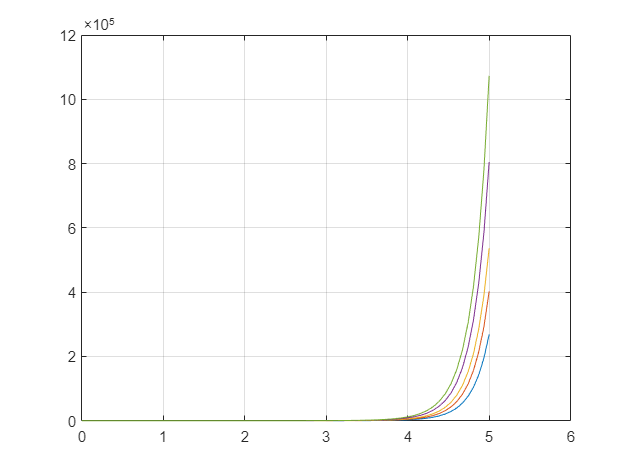

%initial conditions 
close all;

y0_1 = 1;
y0_2 = 1.5;
y0_3 = 2;
y0_4 = 3;
y0_5 = 4;

% y0 = 1
tspan = [0 5];
[t_1, y_1] = ode45(@myode1, tspan, y0_1);
plot(t_1,y_1)
grid on
hold on
% y0 = 1.5
tspan = [0 5];
[t_2, y_2] = ode45(@myode1, tspan, y0_2);
plot(t_2,y_2)
grid on
hold on
% y0 = 2
tspan = [0 5];
[t_3, y_3] = ode45(@myode1, tspan, y0_3);
plot(t_3,y_3)
grid on
hold on
% y0 = 3
tspan = [0 5];
[t_4, y_4] = ode45(@myode1, tspan, y0_4);
plot(t_4,y_4)
grid on
hold on
% y0 = 4
tspan = [0 5];
[t_5, y_5] = ode45(@myode1, tspan, y0_5);
plot(t_5,y_5)
grid on
xlim([0,6]);

***Problem 9:***

$H(s) = \frac{Y(s)}{X(s)} =  \frac{50}{(s+5)(s+10)} = \frac{10}{s+5} + \frac{-10}{s+10}$ which suggests $50X(s) = (s^2 + 15s + 50)Y(s)$. Now that we know $H(s)$, we can get the simulation done with the help of matlab's $lsim$ commmand. 

As you can see is in synch with our result in the previous chapter. 

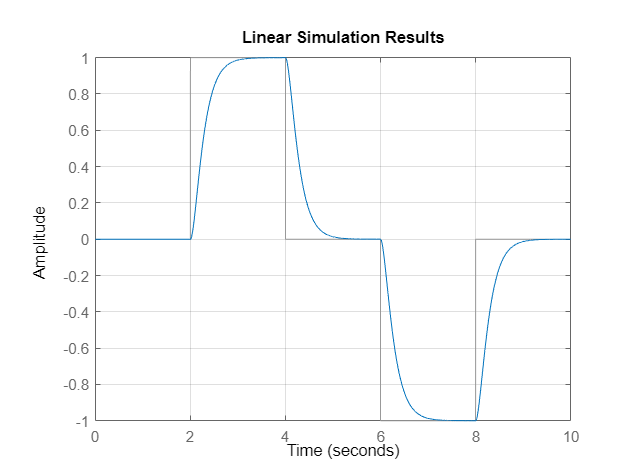

close all;
clear all;
s = tf('s');
H_sys = 50/((s+5)*(s+10));
Ts = 0.001;
tt = 0:Ts:10;
uu = ((tt>=2)&(tt<=4));
uu = uu - ((tt<=8)&(tt>=6));
lsim(H_sys,uu,tt)
grid on

$H(s) = \frac{Y(s)}{X(s)} =  \frac{50}{(s+5)(s+10)} = \frac{10}{s+5} + \frac{-10}{s+10}$ which suggests $50X(s) = (s^2 + 15s + 50)Y(s)$ which implies $50 x(t) = y"(t) + 15y'(t) + 50y(t)
$ . Now if we let $y_d [n] = y(t = nh)$ then we get: 

$
 y'(t) \equiv  \frac{y_d[n] - y_d[n-1]}{h}$  and $y''(t) \equiv \frac{y_d[n]- 2y_d[n-1] + y_d[n-2]}{h^2}$ .

 Which will result in:


$$50x(t) = 50x_d[n]= \frac{1}{h^2}(y_d[n]- 2y_d[n-1] + y_d[n-2]) +  \frac{15}{h}(y_d[n] - y_d[n-1]) + 50y_d[n]$$
 

which follows:


$$y_d[n] (\frac{1}{h^2} + \frac{15}{h} + 50 ) = (\frac{2}{h^2} - \frac{15}{h}) y_d[n-1] - \frac{1}{h^2} y_d[n-2] + 50x[n]$$
 

and by approximation we get:

$y_d[n] (16 + 50h) = 50hx[n] +17 y_d [n-1] - y_d [n-2]$ .

Finally, this is the implementation of the Euler's method for the differential equation:

As you can see, the output is also in sunvh with the results above and the result from part 6. 

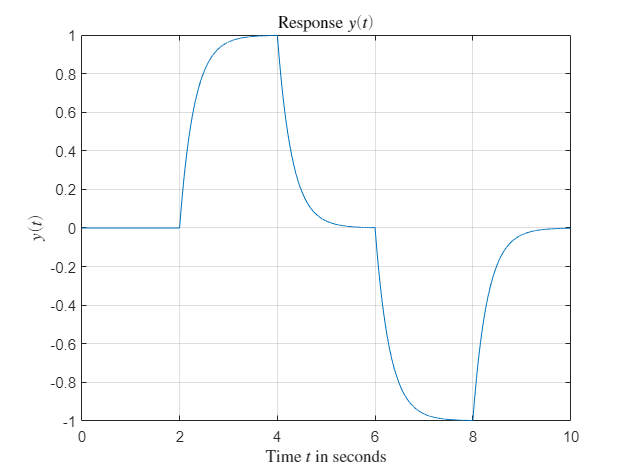

clc;
clear all;
close all;
% defining the sampling rate
Ts = 0.001;
h = Ts;
% the interval's boundaries
t_start =0;
t_end = 10;
% Create a time vector 't'
t = 0:Ts:10;
% Define the input signal 'X' and the output signal 'Y'
U = heaviside(t-2) - heaviside(t-4) - heaviside(t-6) + heaviside(t-8);
X = ((t >= 2) & (t <= 4)) - ((t >= 6) & (t <= 8));
Y = zeros(size(t));
% Set the initial conditions for Y 
Y(1) = 0;
Y(2) = 0;
% Loop to solve the difference equation
for i = 3:length(t)
    Y(i) = g(i, Y(i-1), Y(i-2), X(i), h); 
end
% Plotting the result
plot(t,Y);
title('Response $y(t)$',Interpreter='latex');
xlabel('Time $t$ in seconds', Interpreter='latex');
ylabel('$y(t)$',Interpreter='latex');
grid on;

function [dydt1] = myode1(t, y)
dydt1 = t*y;
end


function [result] = f(i, y_i1, y_i2, u , h)
result =  -(-50*(h^2)*u + (y_i1*(15*h -2)/(h^2)) + (y_i2/(h^2)))/(1 + 15*h + h^2);
end

function [result] = g(i, y_i1, y_i2, u , h)
result =  (50*h*u- y_i2 + 17*y_i1)/(16 + 50*h);
end